close all; clear all;
if ~isfile('PhysionetData.mat')
    ReadPhysionetData        
end
load PhysionetData

set signal

Signals(1:5);
Labels(1:5);
summary(Labels)

     A       738 
     N      5050 


HIstogram

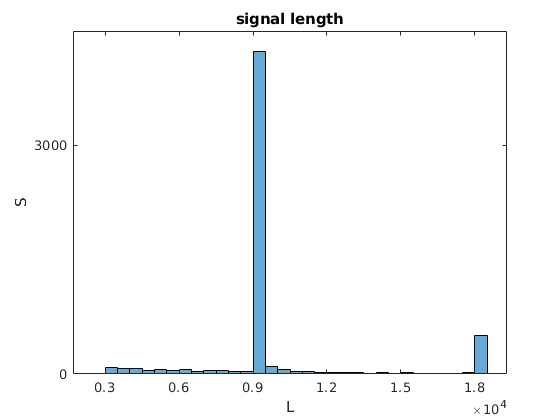

length = cellfun(@length,Signals);
h = histogram(length);
xticks(0:3000:18000);
yticks (0:3000:18000);
title('signal length')
xlabel('L')
ylabel('S')

Segmentation

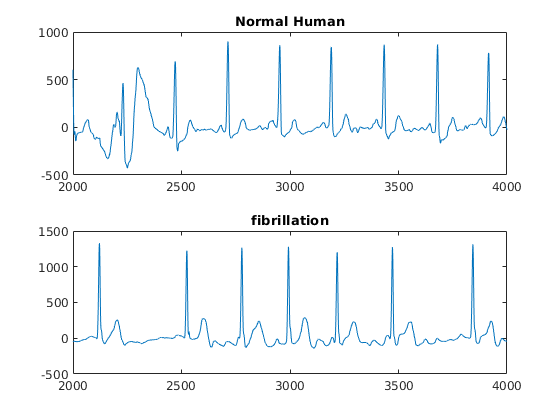

fibrilltion = Signals{4};
normal = Signals{1};

figure (1)
subplot(2,1,1)
plot(normal)
title("Normal Human")
xlim([2000,4000])

subplot(2,1,2)
plot(fibrilltion)
title('fibrillation')
xlim([2000,4000])

prepare for training

[Signals,Labels] = segmentSignals(Signals,Labels);

Train using raw data

%summary(Labels);

splitting

normalX = Signals(Labels=='N');
normalY = Signals(Labels=='N');

sickX = Signals(Labels=='A');
sickY = Signals(Labels=='A');

divide random

[trainIndA,~,testIndA] = dividerand(718,0.9,0.0,0.1);
[trainIndN,~,testIndN] = dividerand(4937,0.9,0.0,0.1);

XTrainA = sickX(trainIndA);
YTrainA = sickY(trainIndA);
XTrainN = normalX(trainIndN);
YTrainN = normalY(trainIndN);

XTestA = sickX(testIndA);
YTestA = sickY(testIndA);
XTestN = normalX(testIndN);
YTestN = normalY(testIndN);

case all of them have the same label

XTrain = [repmat(XTrainA(1:634),7,1); XTrainN(1:4438)];
YTrain = [repmat(YTrainA(1:634),7,1); YTrainN(1:4438)];

XTest = [repmat(XTestA(1:70),7,1); XTestN(1:490)];
YTest = [repmat(YTestA(1:70),7,1); YTestN(1:490);];

Summary 

summary(YTest)

Check for incorrect argument data type or missing argument in call to function 'summary'.